# Practice NODC Cast work

% Load Data
cd('C:\Users\ajs82292\Desktop\Research\Matlab\Source')
load("02cleanNODC.mat")

% Map
clf
hold on

plot(cx,cy,'k')

Error using plot
Vectors must be the same length.

xlim([-80,-35])
ylim([55,80])
scatter(lon,lat,1,'MarkerFaceColor','b','MarkerEdgeAlpha','0') ;
rectangle('Position',[-47,58.7,4,1],'EdgeColor','red','LineWidth',2)
hold off

%Limit NODC Data to Square only to make interpolation easier
Squarelonindicies = (lon >= -47) & (lon <=-43) ;
lon = lon(Squarelonindicies) ;
lat = lat(Squarelonindicies) ;
sal = sal(Squarelonindicies) ;
temp = temp(Squarelonindicies) ;
mon = mon(Squarelonindicies);
day = day(Squarelonindicies);
yea = yea(Squarelonindicies);
watdep = watdep(Squarelonindicies);
dep = dep(Squarelonindicies) ;
% Lat
Squarelatindicies = (lat >= 58.7) & (lat <=59.7) ;
lon = lon(Squarelatindicies) ;
lat = lat(Squarelatindicies) ;
sal = sal(Squarelatindicies) ;
temp = temp(Squarelatindicies) ;
mon = mon(Squarelatindicies) ;
day = day(Squarelatindicies);
yea = yea(Squarelatindicies);
watdep = watdep(Squarelatindicies) ;
dep = dep(Squarelatindicies) ;

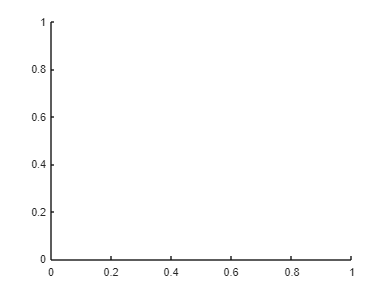

%Map New Restricted Data
clf
hold on
plot(cx,cy,'k')
xlim([-80,-35])
ylim([55,80])
scatter(lon,lat,2,'MarkerFaceColor','b','MarkerEdgeAlpha','0') ;
rectangle('Position',[-47,58.7,4,1],'EdgeColor','red','LineWidth',2)
hold off

%Interpolate every 1 m 
max_length = max(cellfun(@numel,dep)) ;
DepInterval = (0:1:max_length)';
int_temp = {} ;
for i = 1:1:length(dep)
    int_temp{1,i} = interp1(dep{1,i},temp{1,i}, DepInterval, 'linear') ;
end
%Salinity 
int_sal = {} ;
for i = 1:1:length(dep)
    int_sal{1,i} = interp1(dep{1,i},sal{1,i}, DepInterval, 'linear') ;
end

% Set Up Month Matrices
Julyindex = (mon == 7);
Augindex = (mon == 8);
Septindex = (mon == 9);
Octindex = (mon == 10);
JulyT = int_temp(Julyindex) ;
AugT = int_temp(Augindex) ;
SeptT = int_temp(Septindex) ;
OctT = int_temp(Octindex) ;
JulyS = int_sal(Julyindex) ;
AugS = int_sal(Augindex) ;
SeptS = int_sal(Septindex) ;
OctS = int_sal(Octindex) ;
% Matrices for Calculations
JulyT = cell2mat(JulyT);
AugT = cell2mat(AugT);
SeptT = cell2mat(SeptT);
OctT = cell2mat(OctT);
JulyS = cell2mat(JulyS);
AugS = cell2mat(AugS);
SeptS = cell2mat(SeptS);
OctS = cell2mat(OctS);

% Computations
%Averages
JulyTM = mean(JulyT, 2, 'omitnan') ;
AugTM = mean(AugT, 2, 'omitnan') ;
SeptTM = mean(SeptT, 2, 'omitnan') ;
OctTM = mean(OctT, 2, 'omitnan') ;
JulySM = mean(JulyS, 2, 'omitnan') ;
AugSM = mean(AugS, 2, 'omitnan') ;
SeptSM = mean(SeptS, 2, 'omitnan') ;
OctSM = mean(OctS, 2, 'omitnan') ;
% Standard Deviations
JulyTStd = std(JulyT, 0, 2, 'omitnan') ;
AugTStd = std(AugT, 0, 2, 'omitnan') ;
SeptTStd = std(SeptT, 0, 2, 'omitnan') ;
OctTStd = std(OctT, 0, 2, 'omitnan') ;
JulySStd = std(JulyS, 0, 2, 'omitnan');
AugSStd = std(AugS, 0, 2, 'omitnan');
SeptSStd = std(SeptS, 0, 2, 'omitnan');
OctSStd = std(OctS, 0, 2, 'omitnan');

% Subtract Each Cast by monthly Average for Anomaly
JulyTA = JulyT - JulyTM ;
JulySA = JulyS - JulySM ;
AugTA = AugT - AugTM ;
AugSA = AugS - AugSM ;
SeptTA = SeptT - SeptTM ;
SeptSA = SeptS - SeptSM ;
OctTA = OctT - OctTM ;
OctSA = OctS - OctSM ;

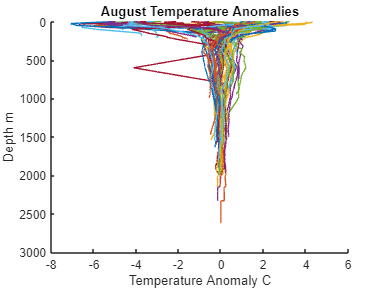

%August TA
clf
hold on
plot(AugTA,DepInterval)
title('August Temperature Anomalies')
xlabel('Temperature Anomaly C')
ylabel('Depth m')
axis ij
hold off

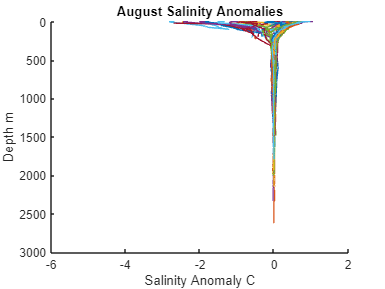

%August Salinity Anmoaly
clf
hold on
plot(AugSA,DepInterval)
title('August Salinity Anomalies')
xlabel('Salinity Anomaly C')
ylabel('Depth m')
axis ij
hold off

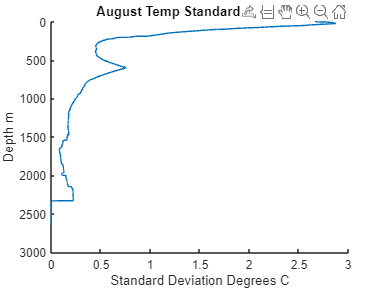

% August Temperature Std
clf
hold on
plot(AugTStd,DepInterval)
title('August Temp Standard Deviation')
xlabel('Standard Deviation Degrees C')
ylabel('Depth m')
axis ij
hold off

% August Salinity Std
clf
hold on

plot(AugSStd,DepInterval)

Unrecognized function or variable 'AugSStd'.

title('August Sal Standard Deviation')
xlabel('Standard Deviation Sal')
ylabel('Depth m')
axis ij
hold off

% Find nearest cx,cy and distance
coastlinepoints = [cx,cy] ;
lonlat = [lon',lat'] ;
idx_nearest = knnsearch(coastlinepoints, lonlat);
closest_cx = cx(idx_nearest);
closest_cy = cy(idx_nearest);
distances = sqrt((lon'-closest_cx).^2 +(lat'-closest_cy).^2) ; % ' to translate lat lon
RadiusEllipse = 15 ; % km, adjust as needed
RadiusEllipse = ones(1,length(distances))* RadiusEllipse ;
insatan = RadiusEllipse./distances' ;
Angle = atan(insatan) ;
Angle = rad2deg(Angle) ;

% Creation of angled ovals, (Circles will come later as they are less
% complicated
R_earth = 6371 ; % km
C_earth = 40075 ;

C_earth = 40075

deltalat = closest_cy'-lat ;
insasin = deltalat./distances' ;
thetarot = asin(insasin) ;

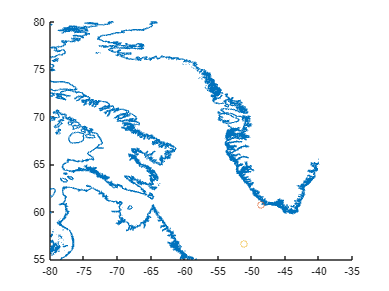

%Test
clf
hold on
plot(cx,cy)
xlim([-80,-35])
ylim([55,80])
scatter(closest_cx(1,1),closest_cy(1,1))
scatter(lon(1,1),lat(1,1))
hold off

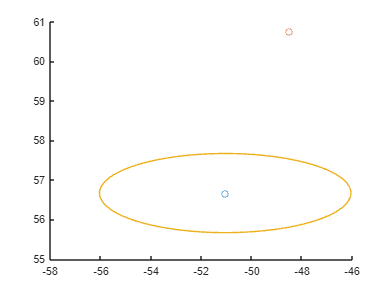

% test
clf
hold on
scatter(lon(1,1),lat(1,1))
scatter(closest_cx(1,1),closest_cy(1,1))
center = [lon(1,1), lat(1,1)] ;
a = 5 ;
b = 1 ;
angle_rad = thetarot(1,1) ; % needs to be different for each ellipse
theta = linspace(0, 2*pi, 100) ; % Angles from 0-2pi
x = center(1) + a * cos(theta);
y = center(2) + b * sin(theta);
R = [cos(angle_rad), -sin(angle_rad); sin(angle_rad), cos(angle_rad)];
plot(x,y)
hold off

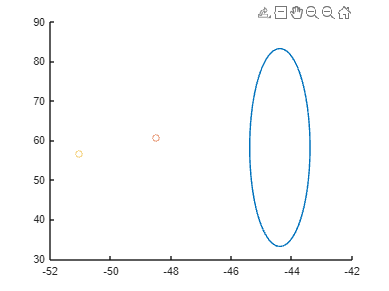

% Test
clf
hold on
tilt_angle = pi/2 ;
a = 25 ;
b = 1 ;
center = [lon(1,1), lat(1,1)] ;
x = center(1) + a * cos(theta);
y = center(2) + b * sin(theta);
x = x - closest_cx(1,1) ;
y = y - closest_cy(1,1) ;
R = [cos(tilt_angle), -sin(tilt_angle); sin(tilt_angle), cos(tilt_angle)];
rotated_coords = R * [x; y];
x = rotated_coords(1, :) + closest_cx(1,1);
y = rotated_coords(2, :) + closest_cy(1,1);
plot(x,y)
scatter(closest_cx(1,1),closest_cy(1,1))
scatter(lon(1,1),lat(1,1))
hold off